# 06 | Animal-level summaries

INPUT: segment_features.csv from step 05. OUTPUT: rat/phase means, own-baseline changes, equally weighted rat summaries. The supplied examples contain TWO rats x THREE phases x TWO selected segments. They demonstrate calculations, not full phase means or manuscript effect sizes.

## 1. Paths and input

codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir=gate_output_dir(codeDir,'06_rat_summary');
T=readtable(fullfile(gate_output_dir(codeDir,'05_band_power'),'segment_features.csv'), ...
    'TextType','string','Delimiter',',','VariableNamingRule','preserve');
assert(all(isfinite(T.Power_dB)),'Resolve missing input values before averaging.');
assert(height(unique(T(:,{'ExampleID','Band'}),'rows'))==height(T),'Duplicate segment/band rows.');

## 2. Average segments within each rat, strategy, phase and band

Include Strategy in every grouping key: different protocols must not mix.

[G,ratID,strategy,phase,band]=findgroups(T.RatID,T.Strategy,T.Phase,T.Band);
nSegments=splitapply(@numel,T.Power_dB,G);
meanPower=splitapply(@mean,T.Power_dB,G);
meanAbsolute=splitapply(@mean,T.AbsolutePower_inputUnitSquared,G);
R=table(ratID,strategy,phase,band,nSegments,meanPower,meanAbsolute, ...
    'VariableNames',{'RatID','Strategy','Phase','Band','NSegments','Power_dB','AbsolutePower_inputUnitSquared'});
writetable(R,fullfile(outDir,'rat_phase_band_power.csv'));

## 3. Normalize each rat to its own Pre value

Signed flattened power can be near zero or negative. Its percentages are not equivalent to percentage changes of positive absolute linear power. No denominator offset, winsorization or data-dependent exclusion is applied.

groups=unique(R(:,{'RatID','Strategy','Band'}),'rows');
rows=cell(0,9);
for k=1:height(groups)
    same=R.RatID==groups.RatID(k) & R.Strategy==groups.Strategy(k) & R.Band==groups.Band(k);
    pre=R.Power_dB(same & R.Phase=="Pre");
    assert(isscalar(pre),'Exactly one animal-level Pre baseline is required.');
    for comparisonPhase=["Stim","Post"]
        phaseValue=R.Power_dB(same & R.Phase==comparisonPhase);
        if isempty(phaseValue),continue;end
        assert(isscalar(phaseValue));
        % This tolerance only prevents division at machine-zero, not a QC cut.
        undefinedBaseline=abs(pre)<=eps(max(1,abs(pre)));
        changePercent=NaN;
        if ~undefinedBaseline,changePercent=100*(phaseValue-pre)/pre;end
        rows(end+1,:)={char(groups.RatID(k)),char(groups.Strategy(k)),char(groups.Band(k)), ...
            char(comparisonPhase),pre,phaseValue,phaseValue-pre,changePercent,undefinedBaseline}; %#ok<SAGROW>
    end
end
C=cell2table(rows,'VariableNames',{'RatID','Strategy','Band','Phase','Pre_dB', ...
    'Phase_dB','Difference_dB','Change_percent','UndefinedBaseline'});
writetable(C,fullfile(outDir,'rat_percent_change.csv'));

## 4. Weight rats equally

SEM uses the number of rats, not the number of 60-s segments.

[G,strategy,phase,band]=findgroups(R.Strategy,R.Phase,R.Band);
nRats=splitapply(@numel,R.Power_dB,G);
groupMean=splitapply(@mean,R.Power_dB,G);
groupSEM=splitapply(@(x)std(x,0)/sqrt(numel(x)),R.Power_dB,G);
groupSEM(nRats<2)=NaN;
summary=table(strategy,phase,band,nRats,groupMean,groupSEM, ...
    'VariableNames',{'Strategy','Phase','Band','NRats','Mean_dB','SEM_dB'});
writetable(summary,fullfile(outDir,'group_descriptive_summary.csv'));

## 5. Aperiodic summaries

These parameters were repeated once per band in step 05. Select exactly one row per segment before averaging, otherwise the same fit is counted six times.

[~,uniqueSegmentRows]=unique(T.ExampleID,'stable'); A=T(uniqueSegmentRows,:);
[G,ratID,strategy,phase]=findgroups(A.RatID,A.Strategy,A.Phase);
offset=splitapply(@mean,A.Offset_dB,G); exponent=splitapply(@mean,A.Exponent,G);
knee=splitapply(@mean,A.Knee,G);
aperiodic=table(ratID,strategy,phase,offset,exponent,knee, ...
    'VariableNames',{'RatID','Strategy','Phase','Offset_dB','Exponent','Knee'});
writetable(aperiodic,fullfile(outDir,'rat_phase_aperiodic.csv'));

## 6. Display matched rats

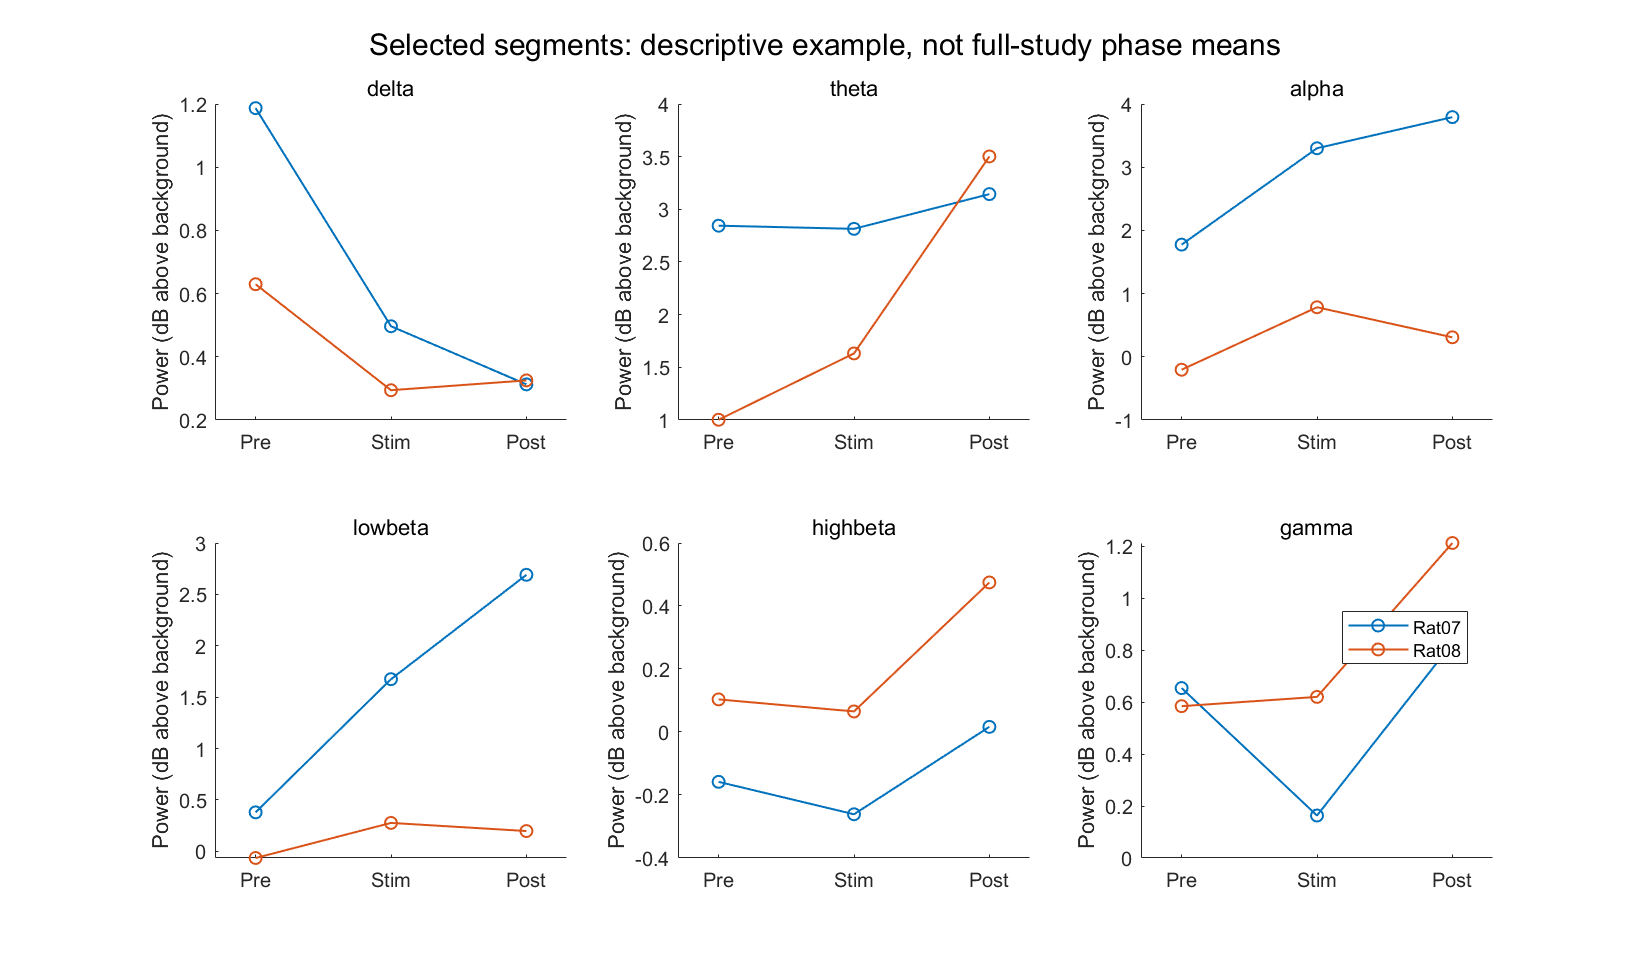

phaseOrder=["Pre","Stim","Post"]; bandOrder=["delta","theta","alpha","lowbeta","highbeta","gamma"];
rats=unique(R.RatID,'stable'); selectedStrategy=R.Strategy(1);
fig=figure('Color','w','Position',[100 100 1100 640]);
for b=1:6
    subplot(2,3,b); hold on;
    for r=1:numel(rats)
        values=NaN(1,3);
        for p=1:3
            mask=R.RatID==rats(r) & R.Strategy==selectedStrategy & R.Band==bandOrder(b) & R.Phase==phaseOrder(p);
            if any(mask),values(p)=R.Power_dB(mask);end
        end
        plot(1:3,values,'-o','LineWidth',1,'DisplayName',char(rats(r)));
    end
    set(gca,'XTick',1:3,'XTickLabel',phaseOrder); xlim([0.7 3.3]);
    ylabel('Power (dB above background)'); title(char(bandOrder(b)));
end
legend('Location','best');
sgtitle('Selected segments: descriptive example, not full-study phase means');
exportgraphics(fig,fullfile(outDir,'animal_level_example.png'),'Resolution',180);

disp(C(1:min(12,height(C)),:));

      RatID        Strategy          Band         Phase       Pre_dB     Phase_dB    Difference_dB    Change_percent    UndefinedBaseline
    _________    ____________    ____________    ________    ________    ________    _____________    ______________    _________________

    {'Rat07'}    {'130Hz_OL'}    {'alpha'   }    {'Stim'}       1.775         3.3          1.525          85.918              false      
    {'Rat07'}    {'130Hz_OL'}    {'alpha'   }    {'Post'}       1.775      3.7924         2.0174          113.66              false      
    {'Rat07'}    {'130Hz_OL'}    {'delta'   }    {'Stim'}      1.1869      0.4967        -0.6902         -58.152              false      
    {'Rat07'}    {'130Hz_OL'}    {'delta'   }    {'Post'}      1.1869     0.31281        -0.8741         -73.645              false      
    {'Rat07'}    {'130Hz_OL'}    {'gamma'   }    {'Stim'}     0.65375     0.16342       -0.49034         -75.003              false      
    {'Rat07'}    {'130Hz_OL'}    